# Linearize Dynamic AGTF30 Model

## Setup Everything

setup_everything();

Inputs gathered from define_inputs.xlsx
Generating ICs with steady-state solver...


## Linearize

% Get linear analysis points
model = 'AGTF30SysDyn';
io = getlinio(model);

% Linearize model
linsys = linearize(model, io)

Warning in AGTF30_eng/Engine/FrontEng/duct2/StaticCalc/S-Function, Error calculating Rt. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/FrontEng/duct2/StaticCalc/S-Function, Error calculating iteration gammasg. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/FrontEng/duct25/StaticCalc/S-Function, Error calculating Rt. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/FrontEng/duct25/StaticCalc/S-Function, Error calculating iteration gammasg. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating WcMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating PRMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating EffMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating 1D SMWcVec. Vector

## Design Controller

szA = size(linsys.A, 1);
rank(ctrb(linsys)) == szA && rank(obsv(linsys)) == szA

ans = logical
   1


linsys_reduced = linsys(:, [2 3])


linsys_reduced =
 
  A = 
                 VBV/1st orde  LP shaft spe  HP speed int  FMV/1st orde
   VBV/1st orde       0.01007             0             0             0
   LP shaft spe        -335.6        0.3059       0.07698         588.6
   HP speed int         694.2        0.3651        0.3559          1573
   FMV/1st orde             0             0             0        0.1353
 
  B = 
                  Wfdmd  VBVdmd
   VBV/1st orde       0  0.9899
   LP shaft spe       0       0
   HP speed int       0       0
   FMV/1st orde  0.8647       0
 
  C = 
                 VBV/1st orde  LP shaft spe  HP speed int  FMV/1st orde
   Control Syst             0        0.3226             0             0
   Control Syst             0             0             1             0
 
  D = 
                  Wfdmd  VBVdmd
   Control Syst       0       0
   Control Syst       0       0
 
Sample time: 0.2 seconds
Discrete-time state-space model.



szA = size(linsys_reduced.A, 1);
rank(ctrb(linsys_reduced)) == szA && rank(obsv(linsys_reduced)) == szA

ans = logical
   1


tfsys = tf(linsys_reduced)


tfsys =
 
  From input "Wfdmd" to output...
                                      164.2 z - 24.64
   Control System/Mux(1):  -------------------------------------
                           z^3 - 0.7971 z^2 + 0.1703 z - 0.01093
 
                                      1360 z - 230.4
   Control System/Mux(2):  -------------------------------------
                           z^3 - 0.7971 z^2 + 0.1703 z - 0.01093
 
  From input "VBVdmd" to output...
                                       -107.2 z + 55.2
   Control System/Mux(1):  ----------------------------------------
                           z^3 - 0.6719 z^2 + 0.08744 z - 0.0008138
 
                                       687.2 z - 331.5
   Control System/Mux(2):  ----------------------------------------
                           z^3 - 0.6719 z^2 + 0.08744 z - 0.0008138
 
Sample time: 0.2 seconds
Discrete-time transfer function.



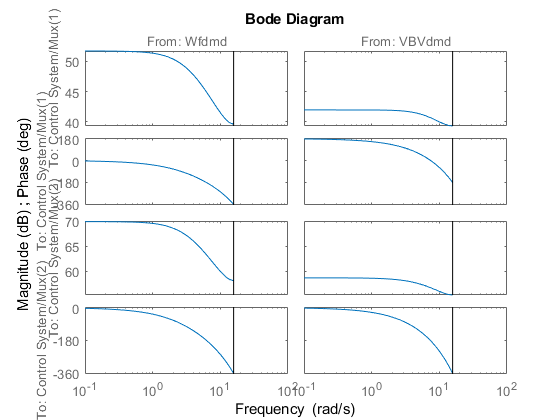

bode(tfsys)

## LQI Design

K = lqi(linsys, diag([0, 15, 5, 0, 3, 1]), diag([1, 0, 0]))

K =        3.8478    0.0012019    0.0019796       6.5506   0.00070888   -0.0020379
     -0.12672   0.00020156   7.9238e-05      0.54613  -0.00040601  -9.6411e-05
     0.079418  -0.00014233   5.9432e-06     -0.21288   0.00072092  -0.00019351


sim("AGTF30SysDyn_controlled.slx");

Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating WcMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating PRMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating EffMap. Vector definitions may need to be expanded.
Warning in AGTF30_eng/Engine/Core/CompressorVG, Error calculating 1D SMWcVec. Vector definitions may need to be adjusted.
